Analysis pipeline for data from "generate_cheater_1x1_fixed.m".

Start point is the data table "cdat" which the above function produces

*What is the figure in the paper? What question specifically is being answered here??

%Data filtering
costfactor = 1;
decayrate = .01; % 1/1800;

timelimit = 400;

d = cdat(mod(log(cdat.alpha),1) == 0,:);
%d = cdat(cdat.sim_complete,:);

d = d(d.costfactor == costfactor,:);
d = d(d.decayrate == decayrate,:);

d.t = cellfun(@(x) x(1:timelimit),d.t,'UniformOutput',false);
d.biomass_cheater= cellfun(@(x) x(1:timelimit),d.biomass_cheater,'UniformOutput',false);
d.biomass_producer = cellfun(@(x) x(1:timelimit),d.biomass_producer,'UniformOutput',false);
d.cellulose_amt = cellfun(@(x) x(1:timelimit),d.cellulose_amt,'UniformOutput',false);
d.glc_amt = cellfun(@(x) x(1:timelimit),d.glc_amt,'UniformOutput',false);
d.enzyme_amt = cellfun(@(x) x(1:timelimit),d.enzyme_amt,'UniformOutput',false);
d.etoh_amt = cellfun(@(x) x(1:timelimit),d.etoh_amt,'UniformOutput',false);
d.timestep = cellfun(@(x) x(1:timelimit),d.timestep,'UniformOutput',false);

%Populate some useful variables for later
[nrows,ncols] = size(d);
alphas = sort(unique(d.alpha));
alphalegend = num2str(alphas(:));
logalphas = log(alphas);
logalphalegend = num2str(logalphas(:));
%colors = jet(length(alphas)); %nx3 vector of colors for plots
%colors = hsv(length(alphas));
colors = hsv(length(alphas)+1);
set(0, 'DefaultLineLineWidth', 2);

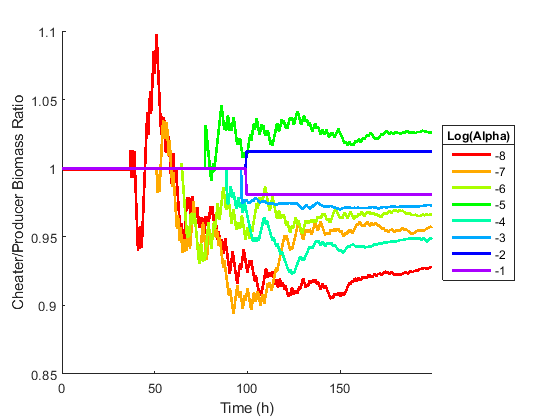

%Plot Cheater/Producer biomass for all alphas
figure;
hold on;
xmax = 0;
ymax = 0;
for i = 1:length(alphas)
    row = d(d.alpha == alphas(i),:);
    bio = row.biomass_cheater{1} ./ row.biomass_producer{1};
    plot(row.t{1},bio,'color',colors(i,:));
    ymax = max(max(bio),ymax);
    xmax = max(max(row.t{1}),xmax);
end
%ylim([0,ymax]);
xlim([0,xmax]);
leg = legend(logalphalegend,'location','eastoutside');
ltitle = get(leg,'title');
set(ltitle,'String','Log(Alpha)');
xlabel('Time (h)')
ylabel('Cheater/Producer Biomass Ratio');
hold off;

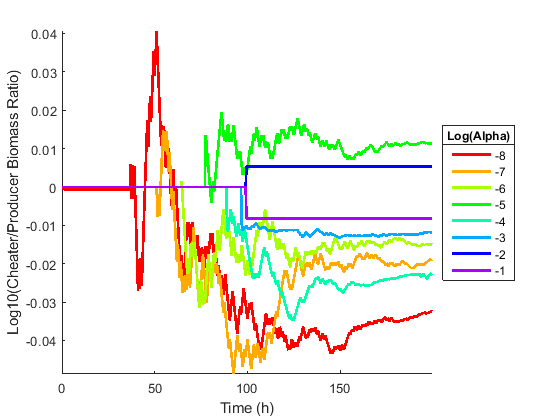


%RESULT: Some plots dip below 1! Same thing, Log10:
figure;
hold on;
xmax = 0;
ymax = 0;
ymin = 0;
for i = 1:length(alphas)
    row = d(d.alpha == alphas(i),:);
    bio = row.biomass_cheater{1} ./ row.biomass_producer{1};
    bio = log10(bio);
    plot(row.t{1},bio,'color',colors(i,:));
    ymax = max(max(bio),ymax);
    xmax = max(max(row.t{1}),xmax);
    ymin = min(min(bio),ymin);
end
ylim([ymin,ymax]);
xlim([0,xmax]);
leg = legend(logalphalegend,'location','eastoutside');
ltitle = get(leg,'title');
set(ltitle,'String','Log(Alpha)');
xlabel('Time (h)')
ylabel('Log10(Cheater/Producer Biomass Ratio)');
hold off;

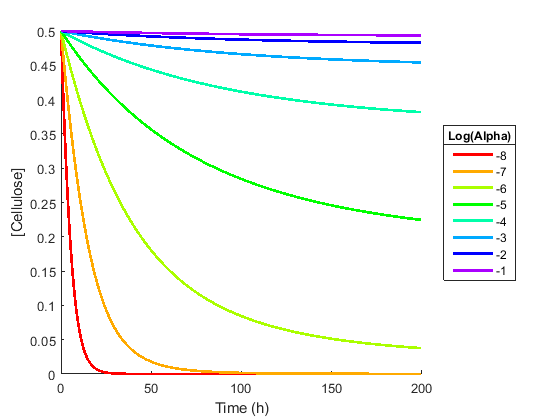

%Cellulose time course
figure;
hold on;
Y = [];
for i = 1:length(alphas)
    Y(:,i) = d.cellulose_amt{i}; 
end
p = plot(d.t{1},Y);
for i = 1:length(p)
    p(i).Color = colors(i,:);
end
leg = legend(logalphalegend,'location','eastoutside');
ltitle = get(leg,'title');
set(ltitle,'String','Log(Alpha)');
xlabel('Time (h)')
ylabel('[Cellulose]')
hold off;

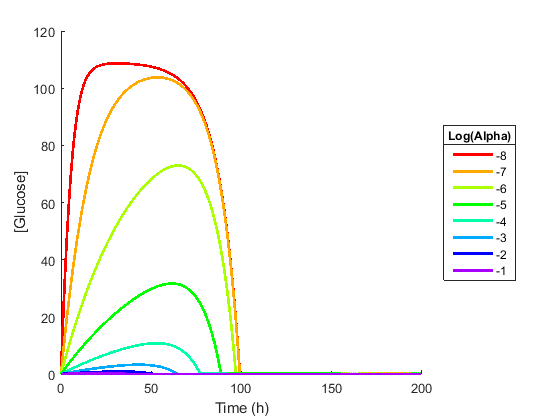

%Glucose time course
figure;
hold on;
Y = [];
for i = 1:length(alphas)
    Y(:,i) = d.glc_amt{i}; 
end
p = plot(d.t{1},Y);
for i = 1:length(p)
    p(i).Color = colors(i,:);
end
leg = legend(logalphalegend,'location','eastoutside');
ltitle = get(leg,'title');
set(ltitle,'String','Log(Alpha)');
xlabel('Time (h)')
ylabel('[Glucose]')
hold off;

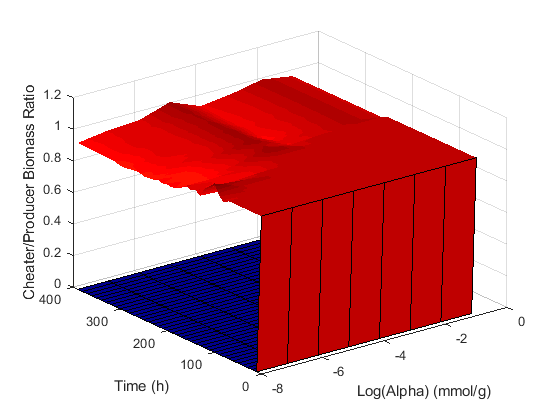

%3D plot of Cheater/Producer biomass for all alphas
%use semilog for the Alpha axis

z_yield = nan(length(alphas),length(d.timestep{1}));
for a = 1:length(alphas)
    row = d(d.alpha == alphas(a),:);
    timestep = row.timestep{1}+1;
    z_yield(a,timestep) = row.biomass_cheater{1} ./ row.biomass_producer{1};
end
logalpha = log(alphas);

[zrows, zcols] = size(z_yield);
reductionfactor = 10; %having too many series then removing lines makes a blank graph
z_yield_sparse = nan(zrows,ceil(zcols/reductionfactor));
for i = 1:reductionfactor:zcols
    z_yield_sparse(:,ceil(i/reductionfactor)) = z_yield(:,i);
end

gridseries = zeros(size(z_yield_sparse));
gridspan = 50;
gridseries(:,1:gridspan:ceil(zcols/reductionfactor)) = z_yield_sparse(:,1:gridspan:ceil(zcols/reductionfactor));

s = surf(logalpha,0:reductionfactor:zcols-1,z_yield_sparse');
set(s,'linestyle','none','facecolor','interp');
xlabel('Log(Alpha) (mmol/g)');
ylabel('Time (h)');
zlabel('Cheater/Producer Biomass Ratio');
colormap jet;
hold on;
s = surf(logalpha,0:reductionfactor:zcols-1,gridseries');
hold off;

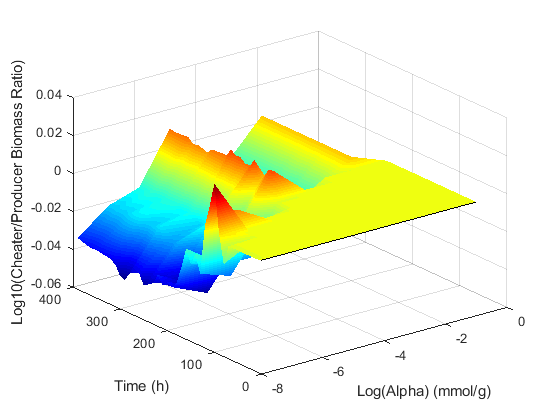


s = surf(logalpha,0:reductionfactor:zcols-1,log10(z_yield_sparse)');
set(s,'linestyle','none','facecolor','interp');
hold on;
s = surf(logalpha,0:reductionfactor:zcols-1,log10(gridseries'));
hold off;
xlabel('Log(Alpha) (mmol/g)');
ylabel('Time (h)');
zlabel('Log10(Cheater/Producer Biomass Ratio)');
colormap jet;

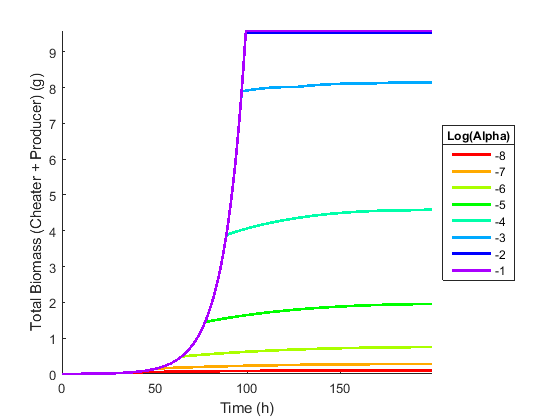

%Total Biomass for all alphas
figure;
hold on;
xmax = 0;
ymax = 0;
for i = 1:length(alphas)
    row = d(d.alpha == alphas(i),:);
    bio = row.biomass_cheater{1} + row.biomass_producer{1};
    plot(row.t{1},bio,'color',colors(i,:));
    ymax = max(max(bio),ymax);
    xmax = max(max(row.t{1}),xmax);
end
ylim([0,ymax]);
xlim([0,xmax]);
leg = legend(logalphalegend,'location','eastoutside');
ltitle = get(leg,'title');
set(ltitle,'String','Log(Alpha)');
xlabel('Time (h)')
ylabel('Total Biomass (Cheater + Producer) (g)');
hold off;

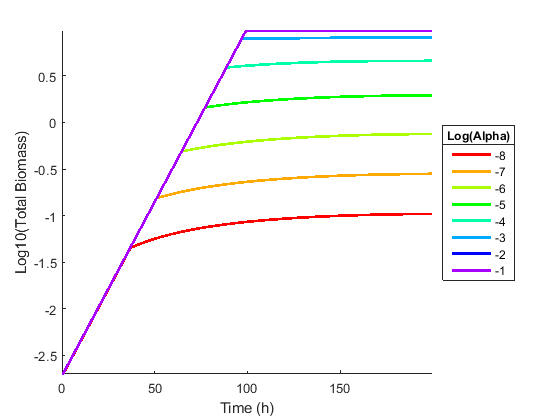


%Total Biomass, Log10:
figure;
hold on;
xmax = 0;
ymax = 0;
ymin = 0;
for i = 1:length(alphas)
    row = d(d.alpha == alphas(i),:);
    bio = row.biomass_cheater{1} + row.biomass_producer{1};
    bio = log10(bio);
    plot(row.t{1},bio,'color',colors(i,:));
    ymax = max(max(bio),ymax);
    xmax = max(max(row.t{1}),xmax);
    ymin = min(min(bio),ymin);
end
ylim([ymin,ymax]);
xlim([0,xmax]);
leg = legend(logalphalegend,'location','eastoutside');
ltitle = get(leg,'title');
set(ltitle,'String','Log(Alpha)');
xlabel('Time (h)')
ylabel('Log10(Total Biomass)');
hold off;

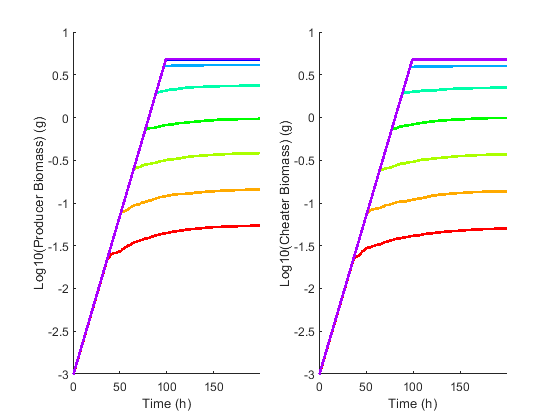

%Biomass of individual species
figure;
subplot(1,2,1);
hold on;
xmax = 0;
ymax = 1;
ymin = 0;
for i = 1:length(alphas)
    row = d(d.alpha == alphas(i),:);
    bio = row.biomass_producer{1};
    bio = log10(bio);
    plot(row.t{1},bio,'color',colors(i,:));
    ymax = max(max(bio),ymax);
    xmax = max(max(row.t{1}),xmax);
    ymin = min(min(bio),ymin);
end
ylim([ymin,ymax]);
xlim([0,xmax]);
%leg = legend(alphalegend,'location','eastoutside');
%ltitle = get(leg,'title');
%set(ltitle,'String','Alpha');
xlabel('Time (h)')
ylabel('Log10(Producer Biomass) (g)');
hold off;

subplot(1,2,2);
hold on;
xmax = 0;
ymax = 1;
ymin = 0;
for i = 1:length(alphas)
    row = d(d.alpha == alphas(i),:);
    bio = row.biomass_cheater{1};
    bio = log10(bio);
    plot(row.t{1},bio,'color',colors(i,:));
    ymax = max(max(bio),ymax);
    xmax = max(max(row.t{1}),xmax);
    ymin = min(min(bio),ymin);
end
ylim([ymin,ymax]);
xlim([0,xmax]);
%leg = legend(alphalegend,'location','eastoutside');
%ltitle = get(leg,'title');
%set(ltitle,'String','Alpha');
xlabel('Time (h)')
ylabel('Log10(Cheater Biomass) (g)');
hold off;

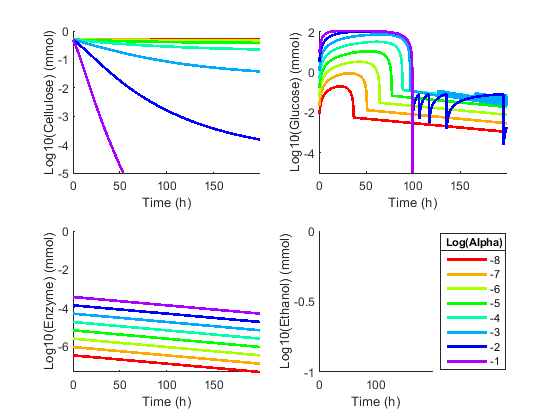

%Timeseries of metabolites- millimolar
figure;
subplot(2,2,1);
hold on;
xmax = 0;
ymax = 0;
ymin = -5;
for i = 1:length(alphas)
    row = d(d.alpha == alphas(i),:);
    bio = row.cellulose_amt{1};
    bio = log10(bio);
    plot(row.t{1},bio,'color',colors(i,:));
    ymax = max(max(bio),ymax);
    xmax = max(max(row.t{1}),xmax);
    %ymin = min(min(bio),ymin);
end
ylim([ymin,ymax]);
xlim([0,xmax]);
%leg = legend(alphalegend,'location','eastoutside');
%ltitle = get(leg,'title');
%set(ltitle,'String','Alpha');
xlabel('Time (h)')
ylabel('Log10(Cellulose) (mmol)');
hold off;

subplot(2,2,2);
hold on;
xmax = 0;
ymax = 0;
ymin = -5;
for i = 1:length(alphas)
    row = d(d.alpha == alphas(i),:);
    bio = row.glc_amt{1};
    bio = log10(bio);
    plot(row.t{1},bio,'color',colors(i,:));
    ymax = max(max(bio),ymax);
    xmax = max(max(row.t{1}),xmax);
    %ymin = min(min(bio),ymin);
end
ylim([ymin,ymax]);
xlim([0,xmax]);
%leg = legend(alphalegend,'location','eastoutside');
%ltitle = get(leg,'title');
%set(ltitle,'String','Alpha');
xlabel('Time (h)')
ylabel('Log10(Glucose) (mmol)');
hold off;

subplot(2,2,3);
hold on;
xmax = 0;
ymax = 0;
ymin = 0;
for i = 1:length(alphas)
    row = d(d.alpha == alphas(i),:);
    bio = row.enzyme_amt{1};
    bio = log10(bio);
    plot(row.t{1},bio,'color',colors(i,:));
    ymax = max(max(bio),ymax);
    xmax = max(max(row.t{1}),xmax);
    ymin = min(min(bio),ymin);
end
ylim([ymin,ymax]);
xlim([0,xmax]);
%leg = legend(alphalegend,'location','eastoutside');
%ltitle = get(leg,'title');
%set(ltitle,'String','Alpha');
xlabel('Time (h)')
ylabel('Log10(Enzyme) (mmol)');
hold off;

subplot(2,2,4);
hold on;
xmax = 0;
ymax = 0;
ymin = 0;
for i = 1:length(alphas)
    row = d(d.alpha == alphas(i),:);
    bio = row.etoh_amt{1};
    bio = log10(bio);
    plot(row.t{1},bio,'color',colors(i,:));
    ymax = max(max(bio),ymax);
    xmax = max(max(row.t{1}),xmax);
    ymin = min(min(bio),ymin);
end
ylim([ymin,ymax]);
xlim([0,xmax]);
leg = legend(logalphalegend,'location','eastoutside');
ltitle = get(leg,'title');
set(ltitle,'String','Log(Alpha)');
xlabel('Time (h)')
ylabel('Log10(Ethanol) (mmol)');
hold off;

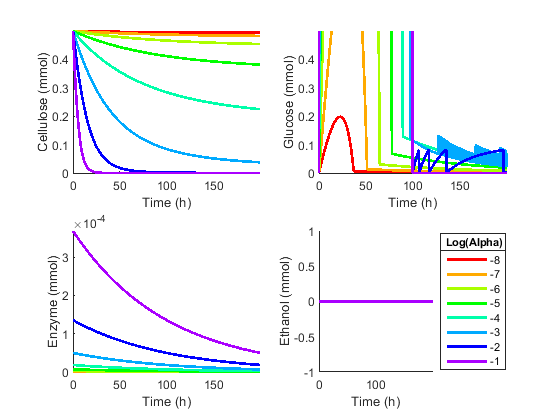

%Timeseries of metabolites- Molar
figure;
subplot(2,2,1);
hold on;
xmax = 0;
ymax = 0;
for i = 1:length(alphas)
    row = d(d.alpha == alphas(i),:);
    bio = row.cellulose_amt{1};
    plot(row.t{1},bio,'color',colors(i,:));
    ymax = max(max(bio),ymax);
    xmax = max(max(row.t{1}),xmax);
    %ymin = min(min(bio),ymin);
end
ylim([0,ymax]);
xlim([0,xmax]);
%leg = legend(alphalegend,'location','eastoutside');
%ltitle = get(leg,'title');
%set(ltitle,'String','Alpha');
xlabel('Time (h)')
ylabel('Cellulose (mmol)');
hold off;

subplot(2,2,2);
hold on;
xmax = 0;
ymax = 0;
for i = 1:length(alphas)
    row = d(d.alpha == alphas(i),:);
    bio = row.glc_amt{1};
    plot(row.t{1},bio,'color',colors(i,:));
    ymax = max(max(bio),ymax);
    xmax = max(max(row.t{1}),xmax);
    %ymin = min(min(bio),ymin);
end
ylim([0,ymax]);
ylim([0 .5]);
xlim([0,xmax]);
%leg = legend(alphalegend,'location','eastoutside');
%ltitle = get(leg,'title');
%set(ltitle,'String','Alpha');
xlabel('Time (h)')
ylabel('Glucose (mmol)');
hold off;

subplot(2,2,3);
hold on;
xmax = 0;
ymax = 0;
ymin = 0;
for i = 1:length(alphas)
    row = d(d.alpha == alphas(i),:);
    bio = row.enzyme_amt{1};
    plot(row.t{1},bio,'color',colors(i,:));
    ymax = max(max(bio),ymax);
    xmax = max(max(row.t{1}),xmax);
    ymin = min(min(bio),ymin);
end
ylim([ymin,ymax]);
xlim([0,xmax]);
%leg = legend(alphalegend,'location','eastoutside');
%ltitle = get(leg,'title');
%set(ltitle,'String','Alpha');
xlabel('Time (h)')
ylabel('Enzyme (mmol)');
hold off;

subplot(2,2,4);
hold on;
xmax = 0;
ymax = 0;
ymin = 0;
for i = 1:length(alphas)
    row = d(d.alpha == alphas(i),:);
    bio = row.etoh_amt{1};
    plot(row.t{1},bio,'color',colors(i,:));
    ymax = max(max(bio),ymax);
    xmax = max(max(row.t{1}),xmax);
    ymin = min(min(bio),ymin);
end
%ylim([ymin,ymax]);
xlim([0,xmax]);
leg = legend(logalphalegend,'location','eastoutside');
ltitle = get(leg,'title');
set(ltitle,'String','Log(Alpha)');
xlabel('Time (h)')
ylabel('Ethanol (mmol)');
hold off;

# Section 2: Analysis for specific Alphas

%pick the lowest, middle, and highest alpha
%a = [alphas(1) alphas(ceil(length(alphas)/2)) alphas(end)];
a = exp([-1 -3 -8])

a =     0.3679    0.0498    0.0003


subtab = d(d.alpha == a(1) | d.alpha == a(2) | d.alpha == a(3),:);
alegend = {['exp(' num2str(log(a(1))) ')'] ['exp(' num2str(log(a(2))) ')'] ['exp(' num2str(log(a(3))) ')']};

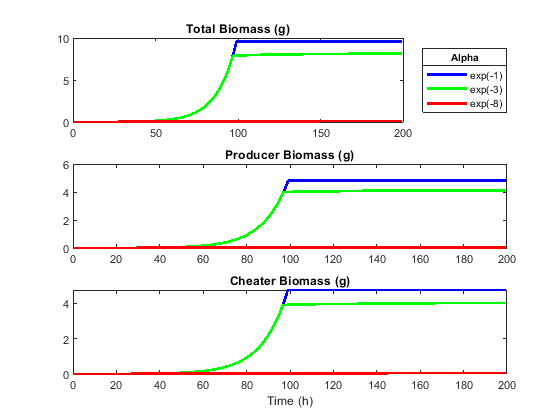

%Biomass side by side
figure;
subplot(3,1,1);
plot(subtab.t{1},subtab.biomass_cheater{1}+subtab.biomass_producer{1},'b',...
    subtab.t{2},subtab.biomass_cheater{2}+subtab.biomass_producer{2},'g',...
    subtab.t{3},subtab.biomass_cheater{3}+subtab.biomass_producer{3},'r');
leg = legend(alegend,'location','eastoutside');
ltitle = get(leg,'title');
set(ltitle,'String','Alpha');
%xlabel('Time (h)')
title('Total Biomass (g)');
%xlim([0 6500]);
subplot(3,1,2);
plot(subtab.t{1},subtab.biomass_producer{1},'b',subtab.t{2},subtab.biomass_producer{2},'g',subtab.t{3},subtab.biomass_producer{3},'r');
%xlabel('Time (h)')
title('Producer Biomass (g)');
%ylim([0 10]);
subplot(3,1,3);
plot(subtab.t{1},subtab.biomass_cheater{1},'b',subtab.t{2},subtab.biomass_cheater{2},'g',subtab.t{3},subtab.biomass_cheater{3},'r');
xlabel('Time (h)')
title('Cheater Biomass (g)');

%ylim([0 10]);


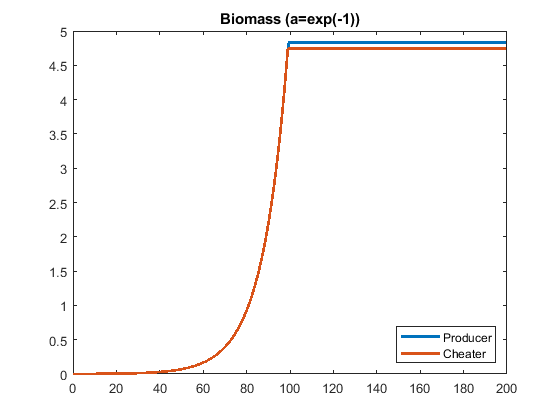

%Biomass as overlaid lines
n = 1;
Y = horzcat(subtab.biomass_producer{n},subtab.biomass_cheater{n});
X = subtab.t{n};
%area(X,Y)
figure();
plot(X,Y)
legend({'Producer' 'Cheater'},'location','southeast')
title(['Biomass (a=exp(' num2str(log(subtab.alpha(n))) '))']);

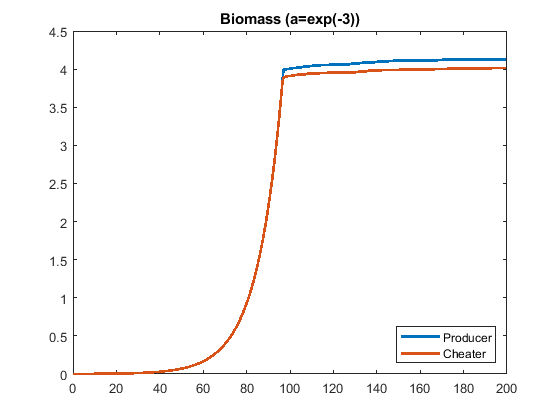


n = 2;
Y = horzcat(subtab.biomass_producer{n},subtab.biomass_cheater{n});
X = subtab.t{n};
%area(X,Y)
figure();
plot(X,Y)
legend({'Producer' 'Cheater'},'location','southeast')
title(['Biomass (a=exp(' num2str(log(subtab.alpha(n))) '))']);

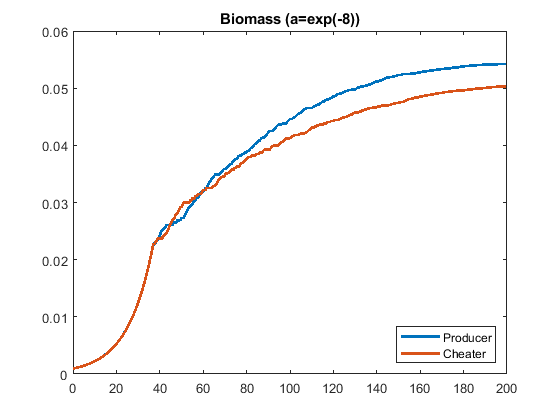


n = 3;
Y = horzcat(subtab.biomass_producer{n},subtab.biomass_cheater{n});
X = subtab.t{n};
%area(X,Y)
figure();
plot(X,Y)
legend({'Producer' 'Cheater'},'location','southeast')
title(['Biomass (a=exp(' num2str(log(subtab.alpha(n))) '))']);

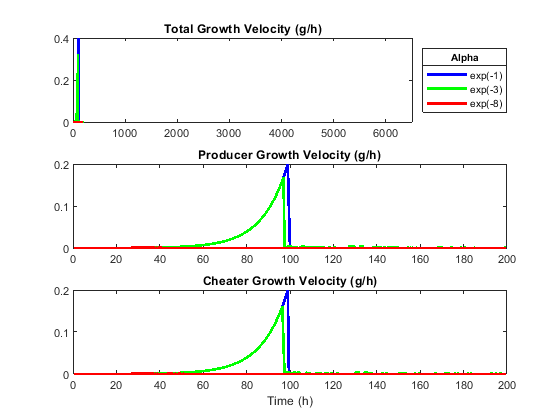

%Growth Velocities (biomass deltas)
[nr nc] = size(subtab);
for i = 1:nr
    subtab.biomass_delta_producer{i} = subtab.biomass_producer{i}(2:end) - subtab.biomass_producer{i}(1:end-1);
    subtab.biomass_delta_cheater{i} = subtab.biomass_cheater{i}(2:end) - subtab.biomass_cheater{i}(1:end-1);
end
figure;
subplot(3,1,1);
plot(subtab.t{1}(2:end),subtab.biomass_delta_cheater{1}+subtab.biomass_delta_producer{1},'b',...
    subtab.t{2}(2:end),subtab.biomass_delta_cheater{2}+subtab.biomass_delta_producer{2},'g',...
    subtab.t{3}(2:end),subtab.biomass_delta_cheater{3}+subtab.biomass_delta_producer{3},'r');
leg = legend(alegend,'location','eastoutside');
ltitle = get(leg,'title');
set(ltitle,'String','Alpha');
%xlabel('Time (h)')
title('Total Growth Velocity (g/h)');
xlim([0 6500]);
subplot(3,1,2);
plot(subtab.t{1}(2:end),subtab.biomass_delta_producer{1},'b',subtab.t{2}(2:end),subtab.biomass_delta_producer{2},'g',subtab.t{3}(2:end),subtab.biomass_delta_producer{3},'r');
%xlabel('Time (h)')
title('Producer Growth Velocity (g/h)');
subplot(3,1,3);
plot(subtab.t{1}(2:end),subtab.biomass_delta_cheater{1},'b',subtab.t{2}(2:end),subtab.biomass_delta_cheater{2},'g',subtab.t{3}(2:end),subtab.biomass_delta_cheater{3},'r');
xlabel('Time (h)')
title('Cheater Growth Velocity (g/h)');

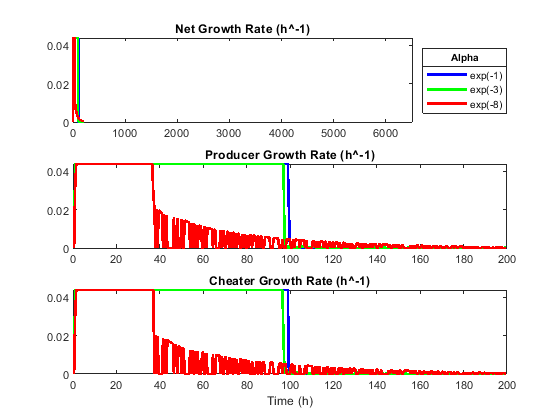

%Growth Rates (as a function of biomass at the previous step)
[nr nc] = size(subtab);
for i = 1:nr
    subtab.biomass_rate_producer{i} = -1 + (subtab.biomass_producer{i}(2:end) ./ subtab.biomass_producer{i}(1:end-1));
    subtab.biomass_rate_cheater{i} = -1 + (subtab.biomass_cheater{i}(2:end) ./ subtab.biomass_cheater{i}(1:end-1));
    subtab.biomass_rate_combined{i} = -1 + ((subtab.biomass_cheater{i}(2:end) + subtab.biomass_producer{i}(2:end)) ./ ...
                                        (subtab.biomass_cheater{i}(1:end-1) + subtab.biomass_producer{i}(1:end-1)));
end
figure;
subplot(3,1,1);
plot(subtab.t{1}(2:end),subtab.biomass_rate_combined{1},'b',...
    subtab.t{2}(2:end),subtab.biomass_rate_combined{2},'g',...
    subtab.t{3}(2:end),subtab.biomass_rate_combined{3},'r');
leg = legend(alegend,'location','eastoutside');
ltitle = get(leg,'title');
set(ltitle,'String','Alpha');
%xlabel('Time (h)')
title('Net Growth Rate (h\^-1)');
xlim([0 6500]);
subplot(3,1,2);
plot(subtab.t{1}(2:end),subtab.biomass_rate_producer{1},'b',subtab.t{2}(2:end),subtab.biomass_rate_producer{2},'g',subtab.t{3}(2:end),subtab.biomass_rate_producer{3},'r');
%xlabel('Time (h)')
title('Producer Growth Rate (h\^-1)');
subplot(3,1,3);
plot(subtab.t{1}(2:end),subtab.biomass_rate_cheater{1},'b',subtab.t{2}(2:end),subtab.biomass_rate_cheater{2},'g',subtab.t{3}(2:end),subtab.biomass_rate_cheater{3},'r');
xlabel('Time (h)')
title('Cheater Growth Rate (h\^-1)');

Question: Why are deltas/rates so noisy?

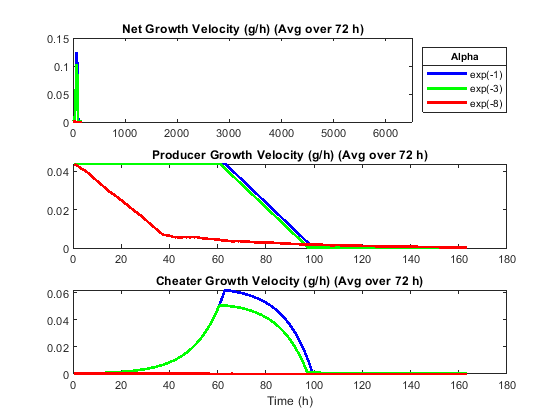

%Growth rates as the average over 10 steps
span = 72;

for i = 1:nr
    brp = subtab.biomass_rate_producer{i};
    bdp = subtab.biomass_delta_producer{i};
    len = length(brp) - span;
    a = zeros(len,1);
    b = zeros(len,1);
    for j = 1:len
        a(j) = mean(brp(j:j+span));
        b(j) = mean(bdp(j:j+span));
    end
    subtab.avg_biomass_rate_producer{i} = a;
    subtab.avg_biomass_delta_producer{i} = a;
    
    brc = subtab.biomass_rate_cheater{i};
    bdc = subtab.biomass_delta_cheater{i};
    len = length(brc) - span;
    a = zeros(len,1);
    for j = 1:len
        a(j) = mean(brc(j:j+span));
        b(j) = mean(bdc(j:j+span));
    end
    subtab.avg_biomass_rate_cheater{i} = a;
    subtab.avg_biomass_delta_cheater{i} = b;
    
    brt = brp + brc;
    bdt = bdp + bdc;
    len = length(brt) - span;
    a = zeros(len,1);
    b = zeros(len,1);
    for j = 1:len
        a(j) = mean(brt(j:j+span));
        b(j) = mean(bdt(j:j+span));
    end
    subtab.avg_biomass_rate_combined{i} = a;
    subtab.avg_biomass_delta_combined{i} = b;
end

figure;
subplot(3,1,1);
plot(subtab.t{1}(2:end-span),subtab.avg_biomass_delta_combined{1},'b',...
    subtab.t{2}(2:end-span),subtab.avg_biomass_delta_combined{2},'g',...
    subtab.t{3}(2:end-span),subtab.avg_biomass_delta_combined{3},'r');
leg = legend(alegend,'location','eastoutside');
ltitle = get(leg,'title');
set(ltitle,'String','Alpha');
%xlabel('Time (h)')
title(['Net Growth Velocity (g/h) (Avg over ' num2str(span) ' h)']);
xlim([0 6500]);
subplot(3,1,2);
plot(subtab.t{1}(2:end-span),subtab.avg_biomass_delta_producer{1},'b',subtab.t{2}(2:end-span),subtab.avg_biomass_delta_producer{2},'g',subtab.t{3}(2:end-span),subtab.avg_biomass_delta_producer{3},'r');
%xlabel('Time (h)')
title(['Producer Growth Velocity (g/h) (Avg over ' num2str(span) ' h)']);
subplot(3,1,3);
plot(subtab.t{1}(2:end-span),subtab.avg_biomass_delta_cheater{1},'b',subtab.t{2}(2:end-span),subtab.avg_biomass_delta_cheater{2},'g',subtab.t{3}(2:end-span),subtab.avg_biomass_delta_cheater{3},'r');
xlabel('Time (h)')
title(['Cheater Growth Velocity (g/h) (Avg over ' num2str(span) ' h)']);

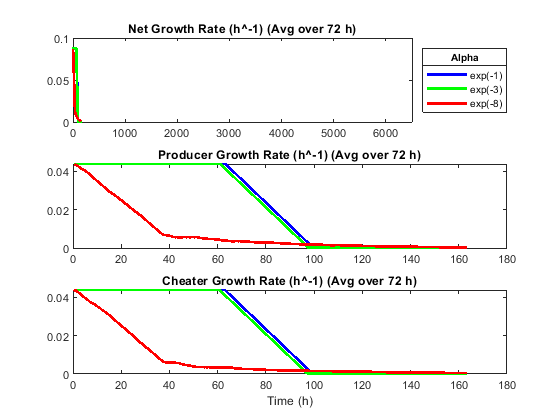


figure;
subplot(3,1,1);
plot(subtab.t{1}(2:end-span),subtab.avg_biomass_rate_combined{1},'b',...
    subtab.t{2}(2:end-span),subtab.avg_biomass_rate_combined{2},'g',...
    subtab.t{3}(2:end-span),subtab.avg_biomass_rate_combined{3},'r');
leg = legend(alegend,'location','eastoutside');
ltitle = get(leg,'title');
set(ltitle,'String','Alpha');
%xlabel('Time (h)')
title(['Net Growth Rate (h\^-1) (Avg over ' num2str(span) ' h)']);
xlim([0 6500]);
subplot(3,1,2);
plot(subtab.t{1}(2:end-span),subtab.avg_biomass_rate_producer{1},'b',subtab.t{2}(2:end-span),subtab.avg_biomass_rate_producer{2},'g',subtab.t{3}(2:end-span),subtab.avg_biomass_rate_producer{3},'r');
%xlabel('Time (h)')
title(['Producer Growth Rate (h\^-1) (Avg over ' num2str(span) ' h)']);
subplot(3,1,3);
plot(subtab.t{1}(2:end-span),subtab.avg_biomass_rate_cheater{1},'b',subtab.t{2}(2:end-span),subtab.avg_biomass_rate_cheater{2},'g',subtab.t{3}(2:end-span),subtab.avg_biomass_rate_cheater{3},'r');
xlabel('Time (h)')
title(['Cheater Growth Rate (h\^-1) (Avg over ' num2str(span) ' h)']);

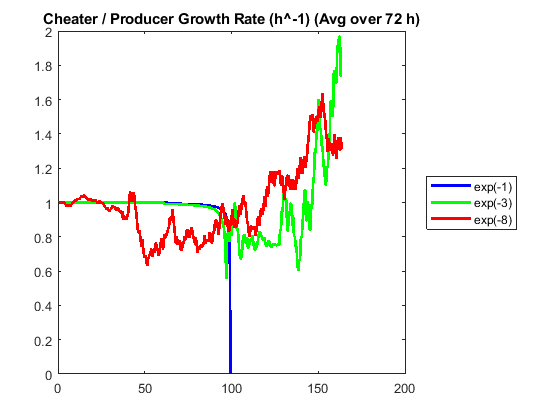

figure;
plot(subtab.t{1}(2:end-span), subtab.avg_biomass_rate_cheater{1} ./ subtab.avg_biomass_rate_producer{1}, '-b', subtab.t{2}(2:end-span), subtab.avg_biomass_rate_cheater{2} ./ subtab.avg_biomass_rate_producer{2}, '-g', subtab.t{3}(2:end-span), subtab.avg_biomass_rate_cheater{3} ./ subtab.avg_biomass_rate_producer{3}, '-r');
legend(alegend,'location','eastoutside');
title(['Cheater / Producer Growth Rate (h\^-1) (Avg over ' num2str(span) ' h)']);

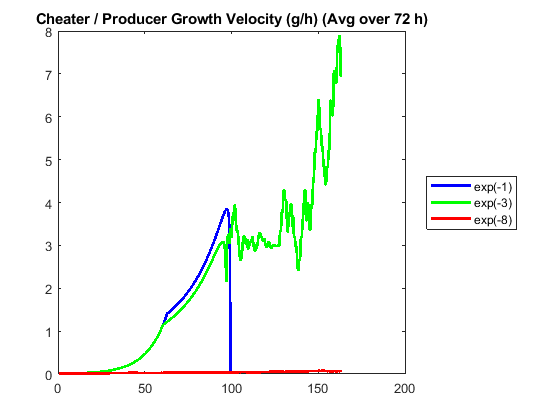

figure;
plot(subtab.t{1}(2:end-span), subtab.avg_biomass_delta_cheater{1} ./ subtab.avg_biomass_delta_producer{1}, '-b', subtab.t{2}(2:end-span), subtab.avg_biomass_delta_cheater{2} ./ subtab.avg_biomass_delta_producer{2}, '-g', subtab.t{3}(2:end-span), subtab.avg_biomass_delta_cheater{3} ./ subtab.avg_biomass_delta_producer{3}, '-r');
legend(alegend,'location','eastoutside');
title(['Cheater / Producer Growth Velocity (g/h) (Avg over ' num2str(span) ' h)']);